# Here we devlop depressive disorders vs controls signatures using rs-fMRI connectivity data

## study 6

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_UESTC_s6.mat'))
load(fullfile(datadir, 'A_cv_pls_study6.mat')) % CV for replication

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
FC = FC(32:end, parcel_idx);
label = [ones(34, 1); -ones(33, 1)];

[~, pred_label] = A_rsfmri_PLS_DA(FC, label, outerCV, innerCV);

Outer fold 1 / 10
Outer fold 2 / 10
Outer fold 3 / 10
Outer fold 4 / 10
Outer fold 5 / 10
Outer fold 6 / 10
Outer fold 7 / 10
Outer fold 8 / 10
Outer fold 9 / 10
Outer fold 10 / 10

Nested CV accuracy = 0.642
Selected components in outer folds:
     4
     5
     1
     4
     6
     4
     3
     2
     4
     1



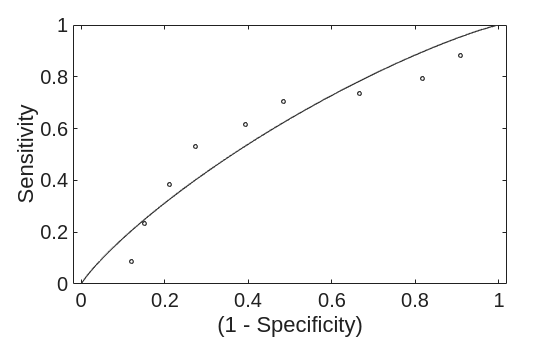

save(fullfile(datadir, 'A_rsfmri_cv_study6.mat'), "pred_label")
% roc_plot uses "0" and "1"
figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0.5, 'nooutput');

fprintf('\n Study 6 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 cross-validated prediction: ACC = 64.18% ± 5.858%, P = 0.0368, AUC = 0.6203, d = 0.3539 


## study 7

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_Chongqing_s6.mat'))
load(fullfile(datadir, 'A_cv_pls_study7.mat')) % CV for replication

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
label = [-ones(24, 1); ones(30, 1)];
included =  patient ~=2;
FC = FC(included, parcel_idx);
label = label(included);

[~, pred_label] = A_rsfmri_PLS_DA(FC, label, outerCV, innerCV);

Outer fold 1 / 10
Outer fold 2 / 10
Outer fold 3 / 10
Outer fold 4 / 10
Outer fold 5 / 10
Outer fold 6 / 10
Outer fold 7 / 10
Outer fold 8 / 10
Outer fold 9 / 10
Outer fold 10 / 10

Nested CV accuracy = 0.739
Selected components in outer folds:
     2
     1
     1
     1
     1
     3
     1
     2
     1
     2



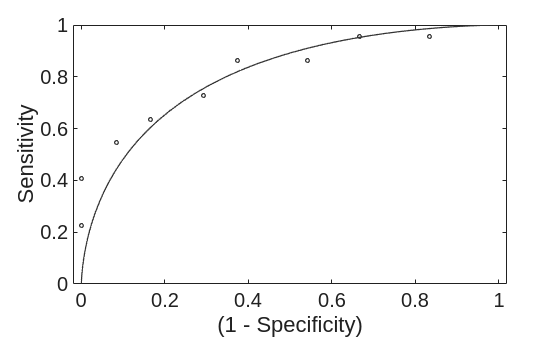

save(fullfile(datadir, 'A_rsfmri_cv_study7.mat'), "pred_label")
% roc_plot uses "0" and "1"
figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0.5, 'nooutput');

fprintf('\n Study 7 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 cross-validated prediction: ACC = 73.91% ± 6.474%, P = 0.004267, AUC = 0.8409, d = 1.237 


## study 8

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_Chongqing2_s6.mat'))
load(fullfile(datadir, 'A_cv_pls_study8.mat')) % CV for replication

FC = atanh(FC);
FC(~isfinite(FC)) = 0;
FC = FC(~excluded, parcel_idx);
label = label(~excluded);
label(label==0) = -1;

[~, pred_label] = A_rsfmri_PLS_DA(FC, label, outerCV, innerCV);

Outer fold 1 / 10
Outer fold 2 / 10
Outer fold 3 / 10
Outer fold 4 / 10
Outer fold 5 / 10
Outer fold 6 / 10
Outer fold 7 / 10
Outer fold 8 / 10
Outer fold 9 / 10
Outer fold 10 / 10

Nested CV accuracy = 0.604
Selected components in outer folds:
     1
     2
     1
     1
     3
     3
     2
     2
     1
     1



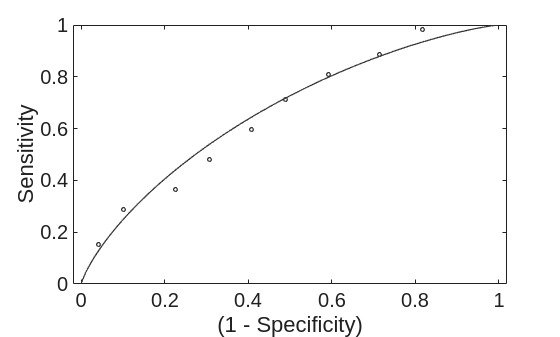

save(fullfile(datadir, 'A_rsfmri_cv_study8.mat'), "pred_label")
% roc_plot uses "0" and "1"
figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0.5, 'nooutput');

fprintf('\n Study 8 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 cross-validated prediction: ACC = 60.4% ± 4.866%, P = 0.08973, AUC = 0.6621, d = 0.6035 


## study 9

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_BANDA_s6.mat'))
load(fullfile(datadir, 'A_cv_pls_study9.mat')) % CV for replication

FC_run1 = atanh(FC_run1);
FC_run1(FC_run1==0) = NaN;
FC_run1(~isfinite(FC_run1)) = NaN;
FC_run1(outlier_run1,:) = NaN; % num of spikes > num of timepoints * 0.25
FC_run2 = atanh(FC_run2);
FC_run2(FC_run2==0) = NaN;
FC_run2(~isfinite(FC_run2)) = NaN;
FC_run2(outlier_run2,:) = NaN; % num of spikes > num of timepoints * 0.25

FC = [];
FC(:, :, 1) = FC_run1;
FC(:, :, 2) = FC_run2;
clear FC_*
FC = mean(FC, 3, 'omitnan');
FC = FC(:, parcel_idx);
excluded_fmri = outlier_run1 & outlier_run2;

T = readtable(fullfile(datadir, 'ndar_subject01.csv'),'VariableNamingRule', 'preserve', 'TreatAsEmpty', 'n/a');
control = false(206,1);
depression = false(206,1);
anxiety = false(206,1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.visit,'T1');
    if sum(idx) == 1
    if strcmp(T.phenotype(idx),'Control')
        control(i) = true;
    elseif strcmp(T.phenotype(idx),'Depression')
        depression(i) = true;
    elseif strcmp(T.phenotype(idx),'Anxiety')
        anxiety(i) = true;
    end
    end
end

FC_depr = FC(depression & ~excluded_fmri,:);
FC_con = FC(control & ~excluded_fmri,:);
clear FC
ndepr = size(FC_depr, 1);
ncon = size(FC_con, 1);
label = [ones(ndepr,1); -ones(ncon, 1)];
FC = [FC_depr; FC_con];

[~, pred_label] = A_rsfmri_PLS_DA(FC, label, outerCV, innerCV);

Outer fold 1 / 10
Outer fold 2 / 10
Outer fold 3 / 10
Outer fold 4 / 10
Outer fold 5 / 10
Outer fold 6 / 10
Outer fold 7 / 10
Outer fold 8 / 10
Outer fold 9 / 10
Outer fold 10 / 10

Nested CV accuracy = 0.619
Selected components in outer folds:
     3
     3
     1
     4
     3
     6
     3
     2
     3
     5



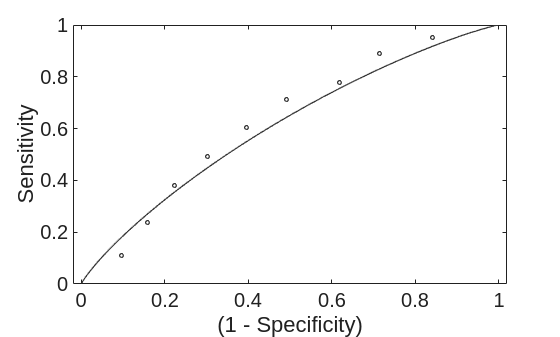

save(fullfile(datadir, 'A_rsfmri_cv_study10.mat'), "pred_label")
% roc_plot uses "0" and "1"
figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0.5, 'nooutput');

fprintf('\n Study 9 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 cross-validated prediction: ACC = 61.9% ± 4.326%, P = 0.009503, AUC = 0.6367, d = 0.3891 
